# MEMS Parametric Optimization using LSM and the adjoint formulation

*Example run on a laptop equipped with an Intel(R) Core(TM) Ultra 9 185H CPU @2.50GHz, 32GB RAM @5600MT/s.*

In this example, we tune the nonlinear coefficient of the reduced dynamics on a 3rd-order expansion of the **Lyapunov Subcenter Manifold** (LSM) using parametric optimization (`fmincon`). **Sensitivities** are computed efficiently using the **adjoint method**.

The system we consider is a MEMS gyroscope prototype (named TS4), which is modelled using the **Multi-Point Constraint** (MPC) method: masses are represented by rigid bodies, connected to beams with a master-slave approach. In this demo, we also tune the drive and sense vibration modes to be at specific target frequencies in order to test the mode-tracking algorithm.

References:

- *MEMS model*: Marconi J. et al., "[Exploiting Nonlinearities for Frequency-Matched MEMS Gyroscopes Tuning](https://doi.org/10.1109/INERTIAL51137.2021.9430478)", INERTIAL, 2021*.*

- *LSM Optimization*: Pozzi M., Marconi J., Jain S. & Braghin F., "[Backbone curve tailoring via Lyapunov subcenter manifold optimization](https://doi.org/10.1007/s11071-024-09881-5)", Nonlinear Dynamics, 2024.

- *Adjoint formulation*: Mingwu Li, "[Explicit sensitivity analysis of spectral submanifolds of mechanical systems](https://doi.org/10.1007/s11071-024-09947-4)", Nonlinear Dynamics, 2024.

- *Multi-Point Constraint:* see class `"../src/misc/MultiPointConstraint.m". `For a tutorial, refer to "`../examples/Mechanical/mpc/demo_mpc.mlx`"

clear; close all; clc

addpath ..\..\examples\Mechanical\mpc
run ..\..\startup.m

              _____ _____     
  _   _  __ _|  ___| ____|___ 
 | | | |/ _` | |_  |  _| / __|
 | |_| | (_| |  _| | |__| (__ 
  \__, |\__,_|_|   |_____\___|
  |___/       YetAnotherFEcode




## Model definition (example)

Use the below parameters to change the geometry of the structure. Below, find an example with some random parameters:

p(1) =  20; % delta length (drive beams)
p(2) = -10; % delta length (sense beams)
p(3) = 1;   % delta width (drive beams)
p(4) = 1;   % delta width (sense beams)
p(5) = 0;   % delta width (sense beam connections)

The drive beam shapes are modified from straight lines into a composition of harmonics. Considering for simplicity a beam aligned with the x-axis, the final coordinates become


$$y=y_o +\sum_{k=1}^5 H_k \;\sin \left(\frac{k\pi }{L}x\right)$$


being $y_o$ the original y-coordinates of the beam.

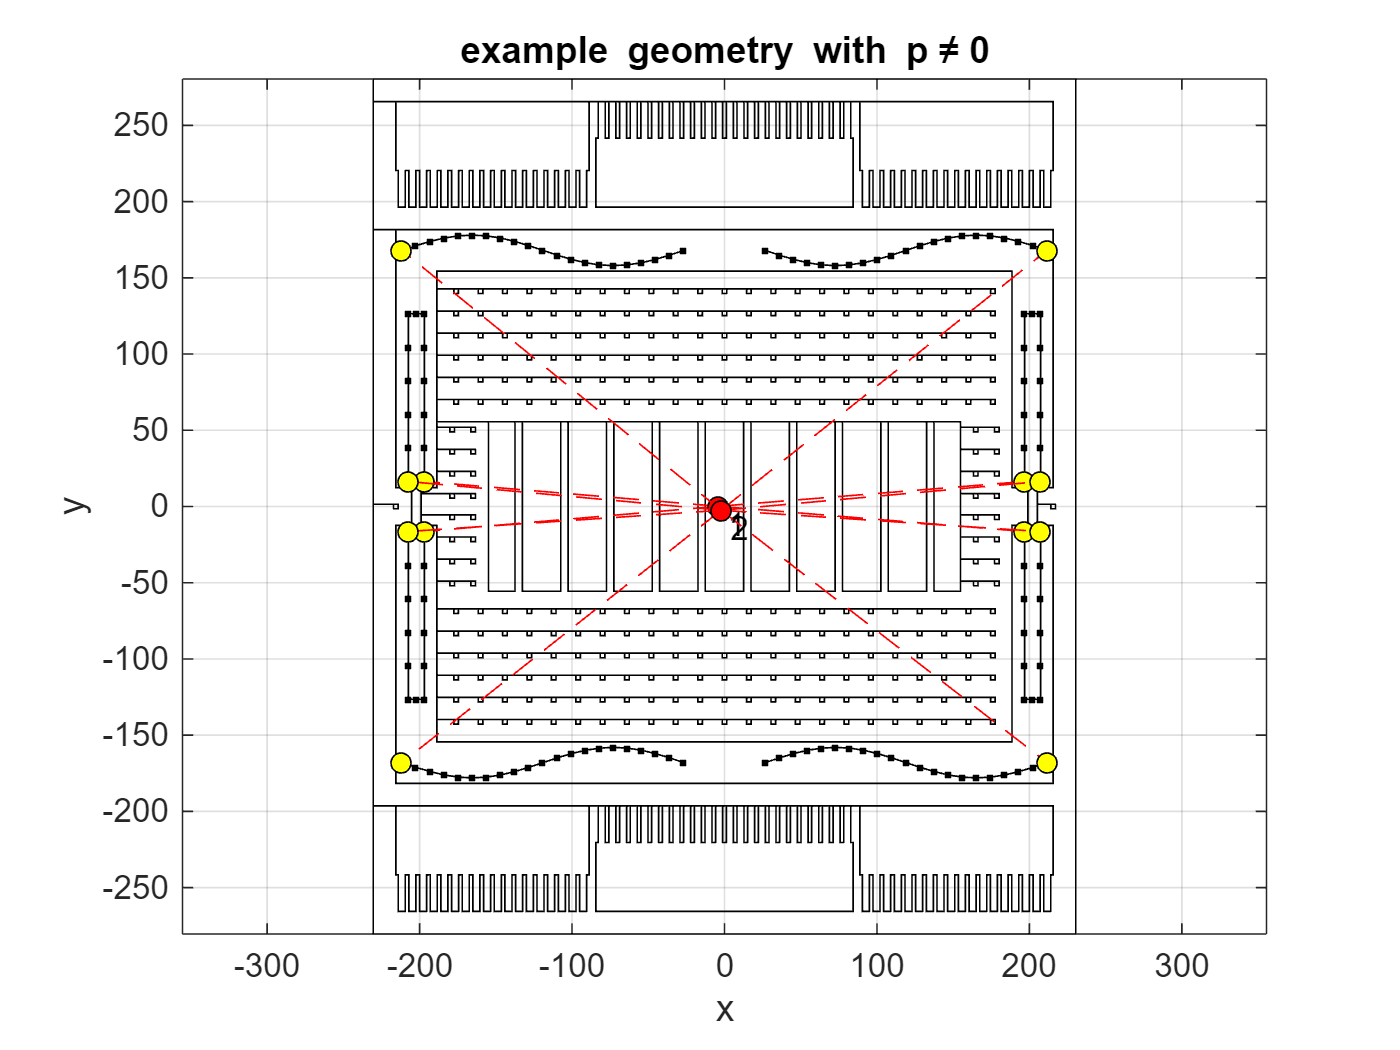

p(6:10)  = [0  10 0 0 0];   % first 5 harmonics for the two TOP drive beams
p(11:15) = [0 -10 0 0 0];   % first 5 harmonics for the two BOTTOM drive beams

obj = build_model(p);
figure
obj.mpc_plot
title('example geometry with p\neq0')

## Preliminary analysis (p=0)

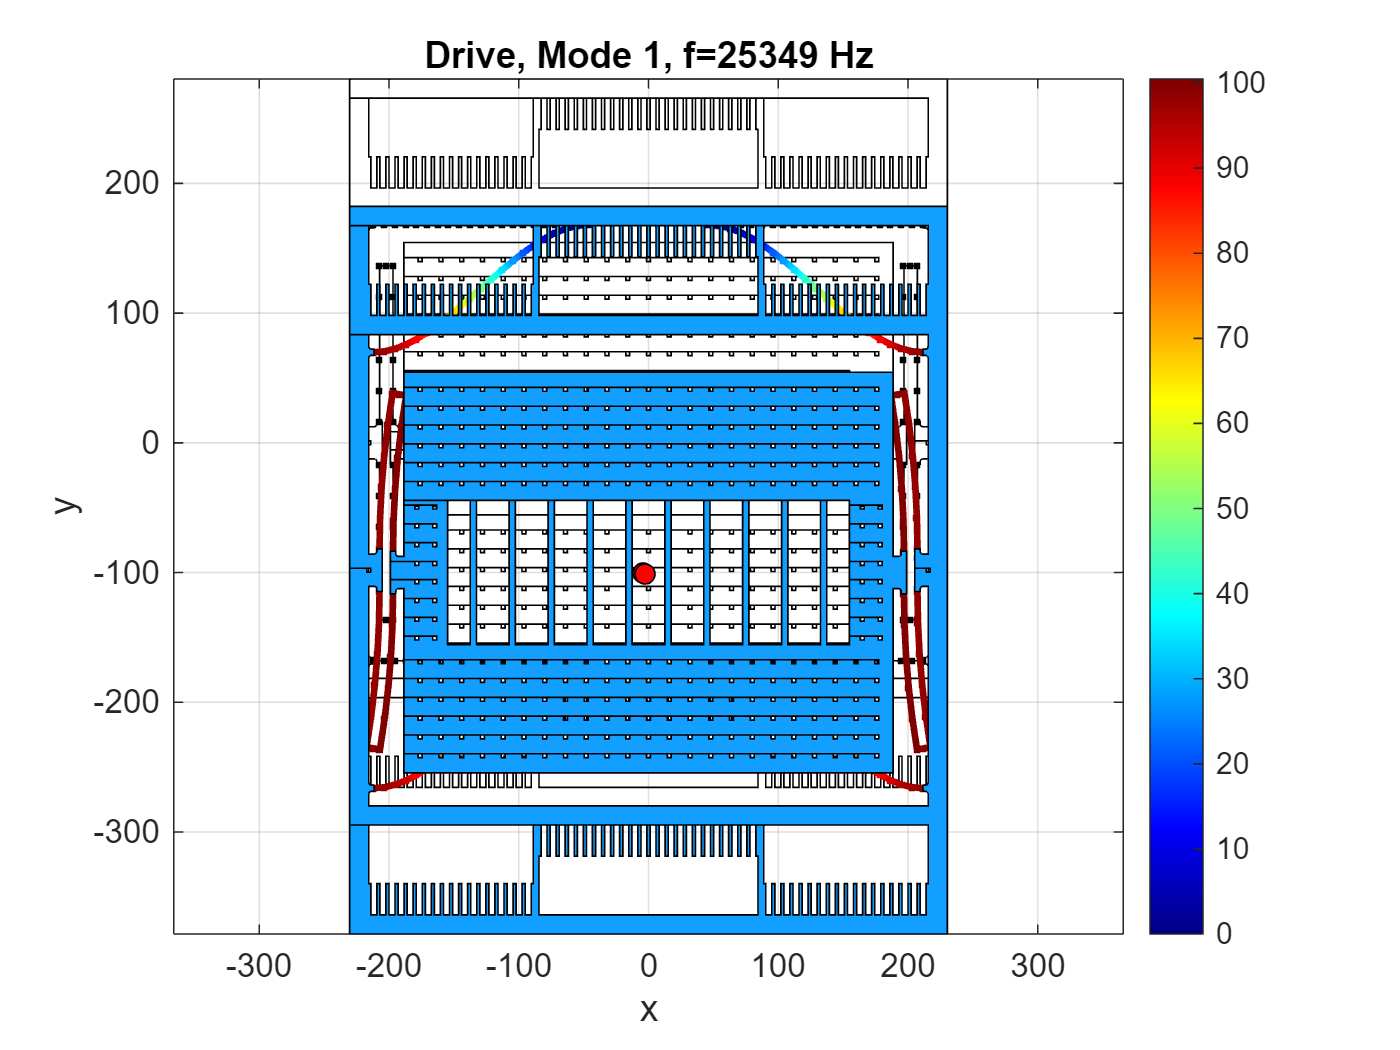

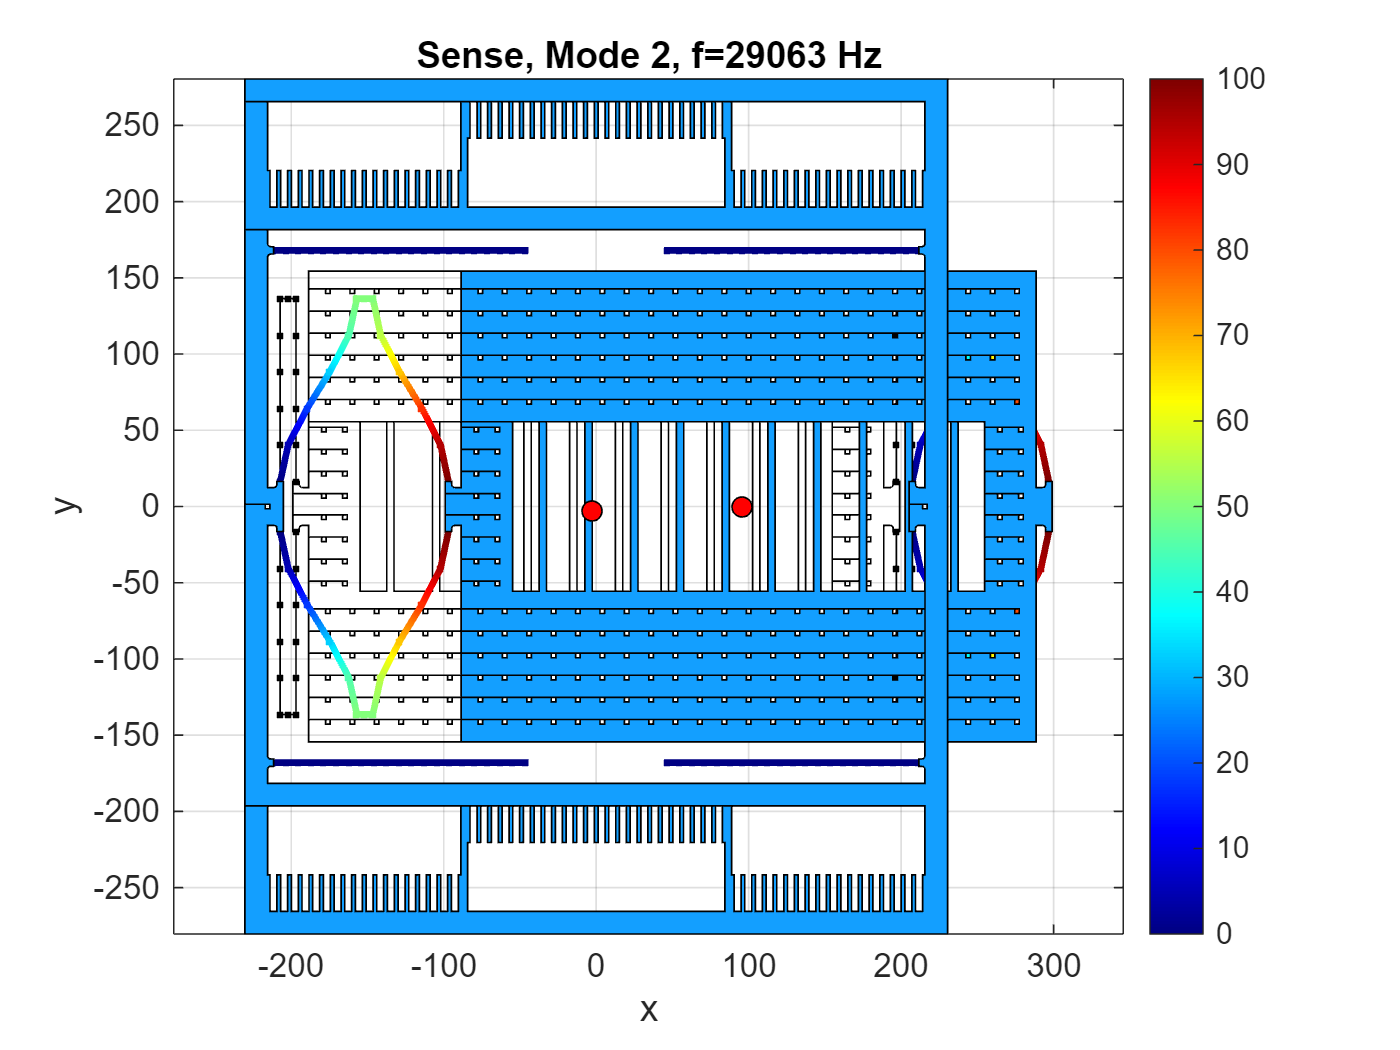

 mode: 1
 dof: 365 
 gamma = 1.32172e+12


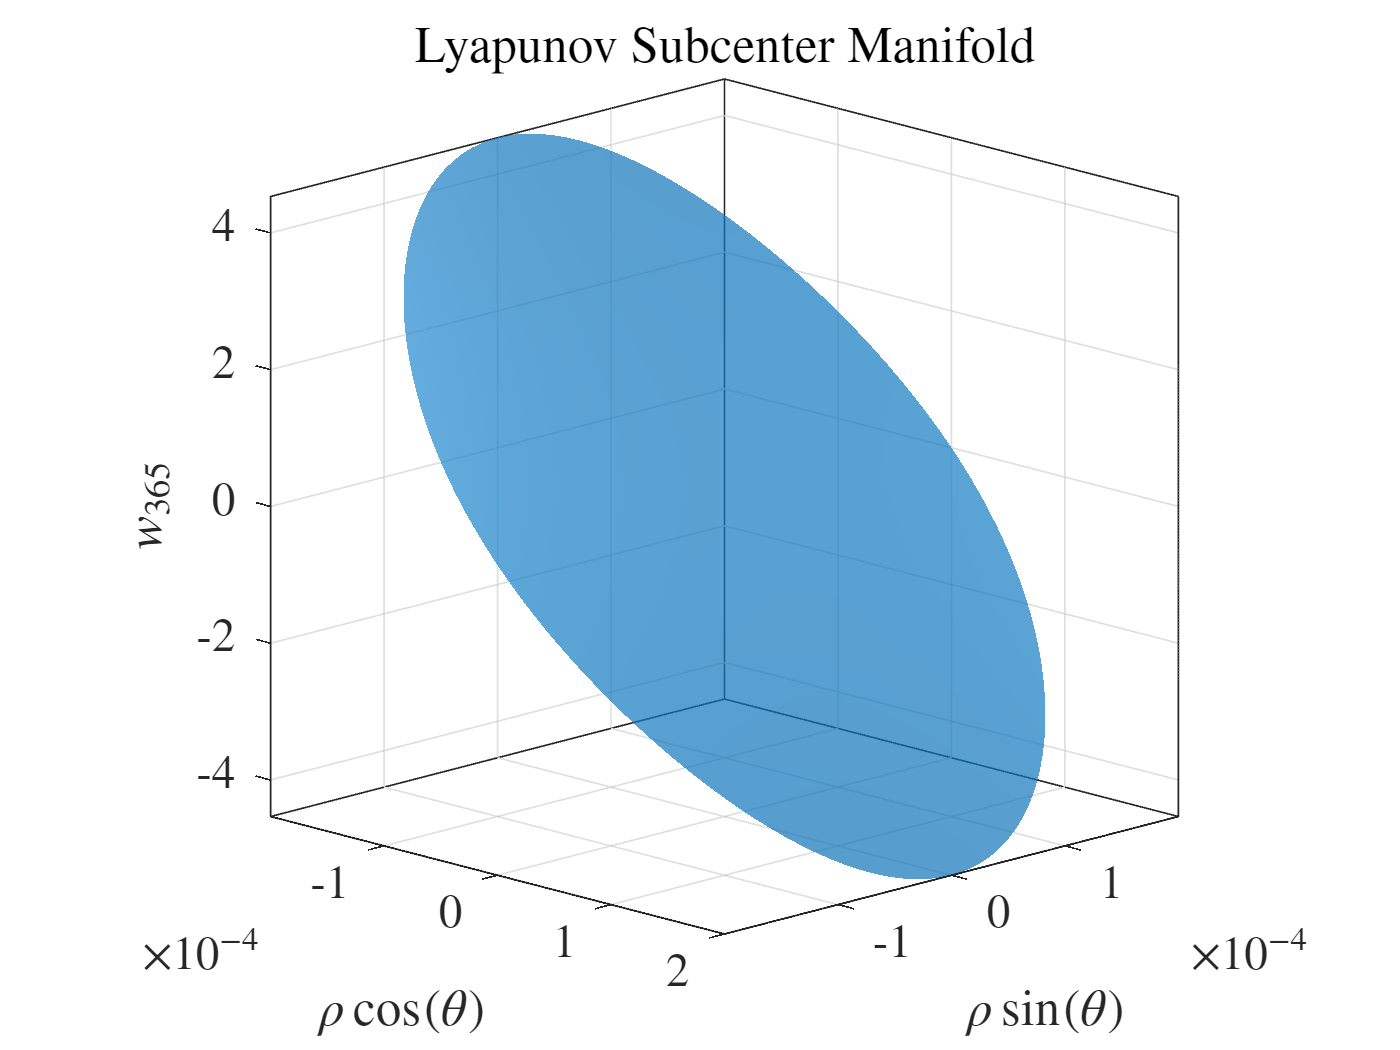

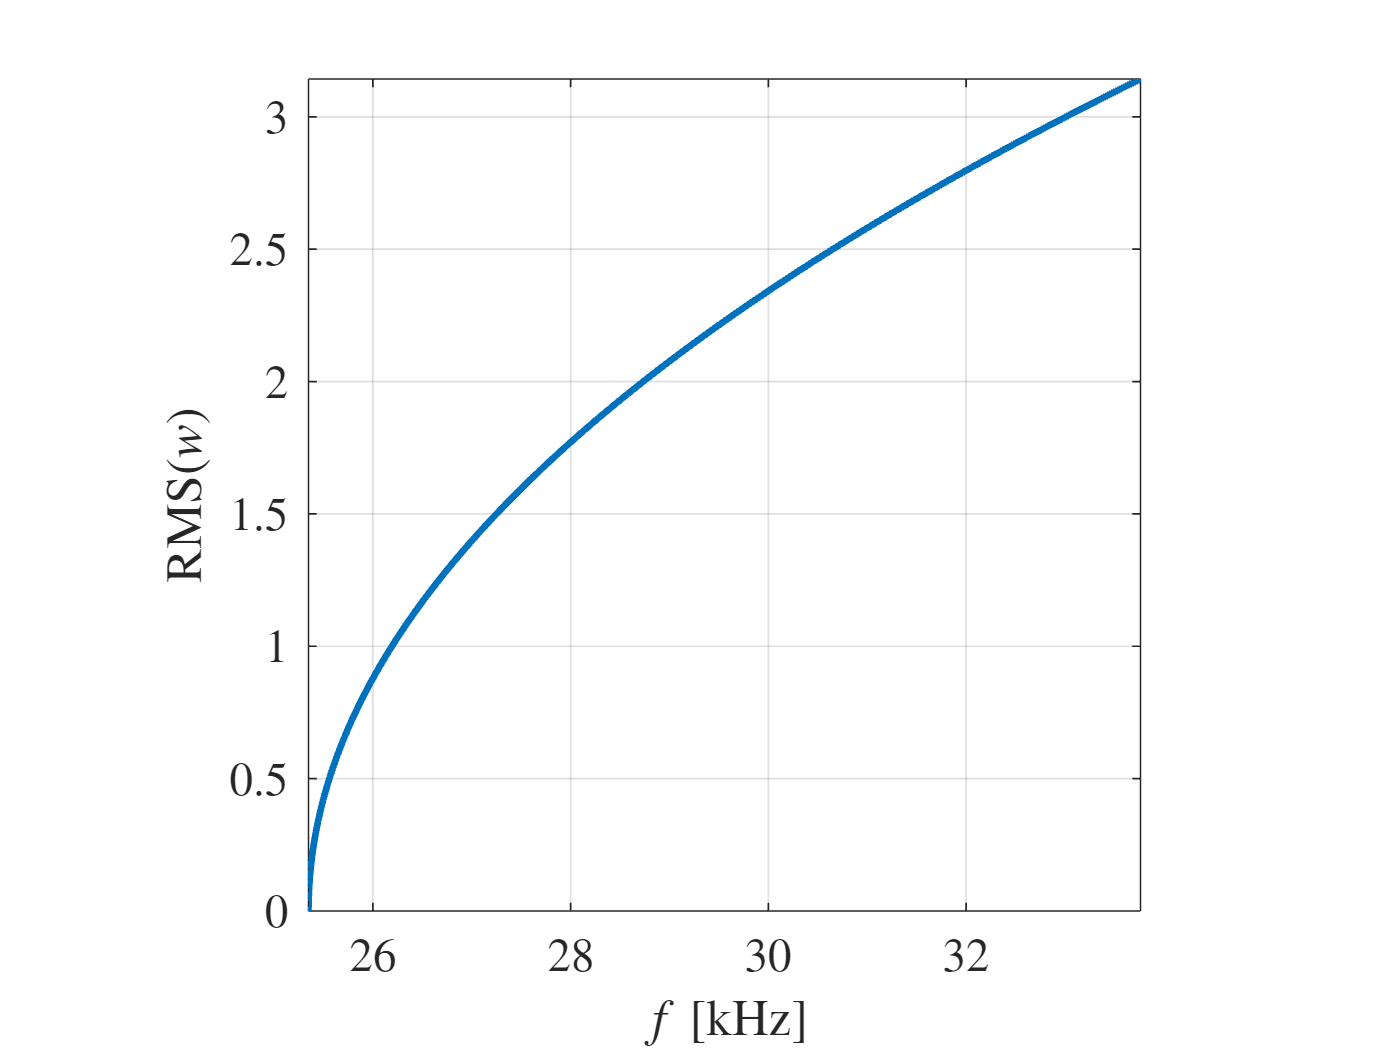

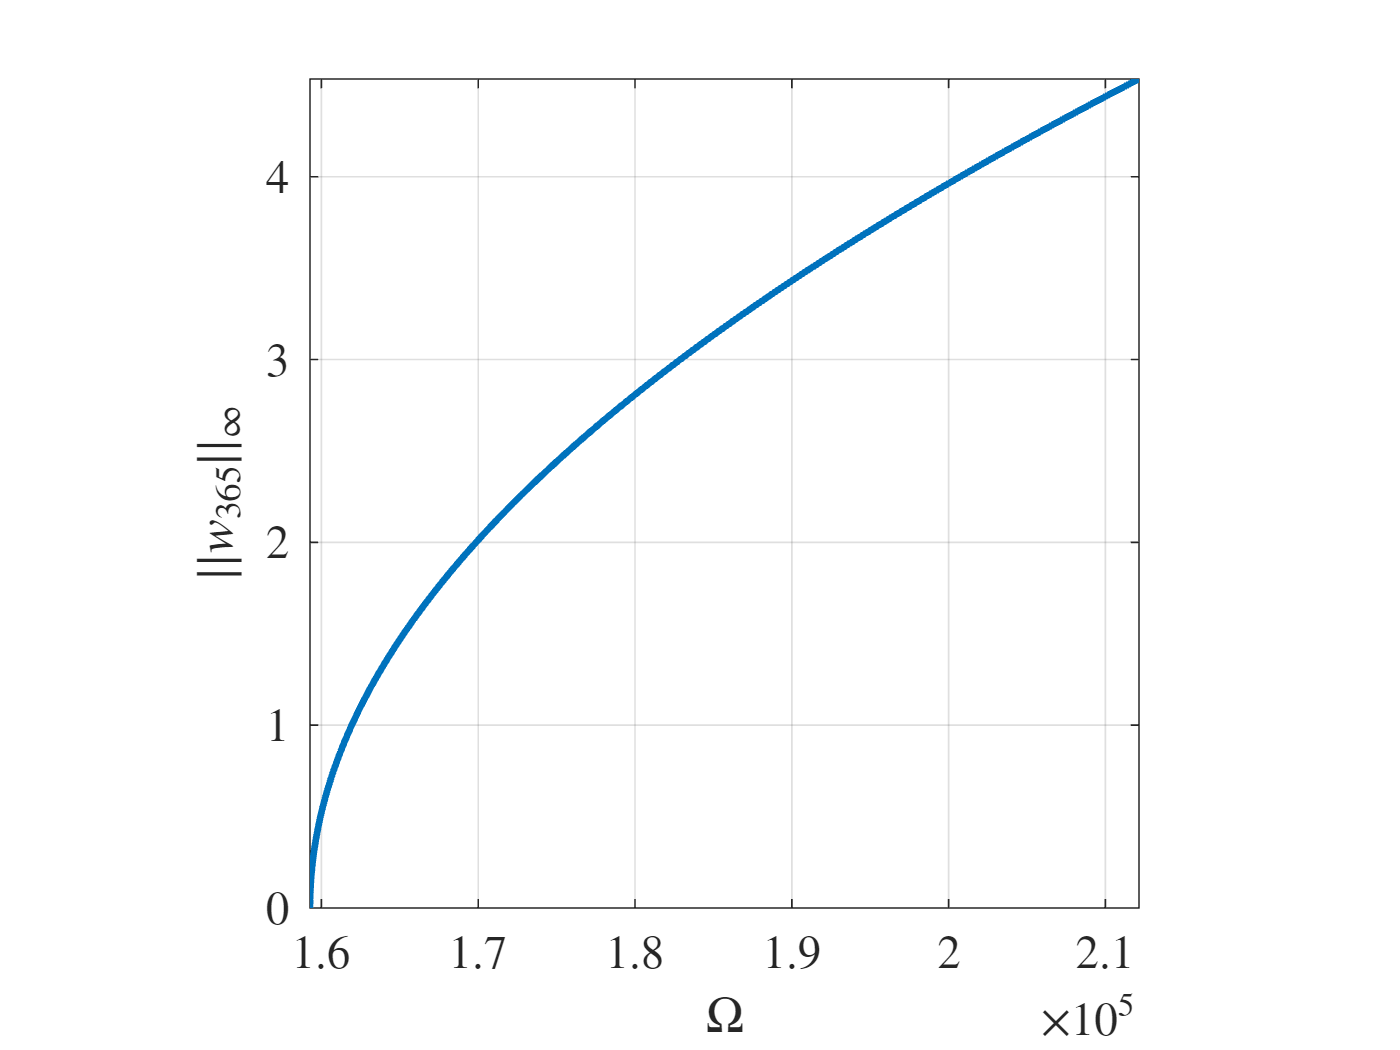

ans = 1.0e+05 *

    1.5927    1.5928    1.5929    1.5932    1.5936    1.5941    1.5947    1.5954    1.5962    1.5971    1.5981    1.5993    1.6005    1.6018    1.6033    1.6049    1.6065    1.6083    1.6102    1.6122    1.6143    1.6165    1.6188    1.6213    1.6238    1.6264    1.6292    1.6320    1.6350    1.6381    1.6413    1.6446    1.6480    1.6515    1.6551    1.6588    1.6626    1.6666    1.6706    1.6748    1.6790    1.6834    1.6879    1.6925    1.6972    1.7020    1.7069    1.7119    1.7170    1.7222


obj = build_model(p*0);
analyze_system(obj)

Last plot can be used to compare the backbone against the result obtained with the SSMtool.

## Parametric optimization

As often required in MEMS resonators, here we tune the structural modes (drive and sense) to specific target frequencies using `fmincon`.

In this example, we also test the **mode-veering** tracking. This allows us to switch drive and sense modes, originally the 1st and 2nd modes for p=0, respectively.

The **optimization problem** is in the following form:


$$\begin{array}{l}
\min_{\mu \;} \;J\\
s\ldotp t\ldotp \;\;\;\;\frac{\omega_d }{\omega {\;}_{d,\textrm{target}} }-1=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\frac{\omega_s }{\omega {\;}_{s,\textrm{target}} }-1=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\frac{\gamma }{|\gamma_{\textrm{target}} |}-\textrm{sign}\left(\gamma_{\textrm{target}} \right)<0
\end{array}$$


where $\mu$ is the vector of the design variables, $\omega_{d,s}$ are the drive and sense eigenfrequencies, respectively, and the coefficient $\gamma$ defines the **backbone curve** as:

$\Omega =\omega_o +\gamma \rho^2 +O\left(\rho^3 \right)$,

being $\rho$ the reduced amplitude on the **Lyapunov Subcenter Manifold** (LSM). Finally, being interested only in the constraints, here for simplicity J is set to 0.

The sensitivities for $\gamma$ here are computed *analytically* from the 3rd order LSM (multi-index) expression and using the **adjoint method**. This way, only the derivatives of the system matrices (M and K) and tensors (K2 and K3) must be computed using *finite differences*.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    0.000000e+00    1.332e+02    0.000e+00
    1       3    0.000000e+00    1.330e+02    0.000e+00    8.105e-02
    2       4    0.000000e+00    6.953e+01    0.000e+00    2.485e+01
    3       5    0.000000e+00    2.532e-03    0.000e+00    3.130e+00


    4       6    0.000000e+00    6.379e-04    0.000e+00    1.840e-01
    5       7    0.000000e+00    1.603e-04    0.000e+00    1.868e+00
    6       8    0.000000e+00    4.020e-05    0.000e+00    1.863e+00
    7       9    0.000000e+00    1.006e-05    0.000e+00    2.512e-01
    8      11    0.000000e+00    1.415e-06    0.000e+00    2.594e-01
    9      13    0.000000e+00    1.989e-07    0.000e+00    3.513e-01
   10      15    0.000000e+00    2.778e-08    0.000e+00    1.169e+00
   11      17    0.000000e+00    4.430e-06    0.000e+00    2.666e+00
   12      18    0.000000e+00    1.123e-06    0.000e+00    1.937e-01
   13      22    0.000000e+00    5.972e-07    0.000e+00    1.117e+00
   14      25    0.000000e+00    3.128e-08    0.000e+00    1.553e+00
   15      28    0.000000e+00    1.463e-07    0.000e+00    1.379e+00
   16      31    0.000000e+00    7.375e-07    0.000e+00    1.216e+00
   17      32    0.000000e+00    2.692e-06    0.000e+00    2.652e+00
   18      35    0.000000e+00    1

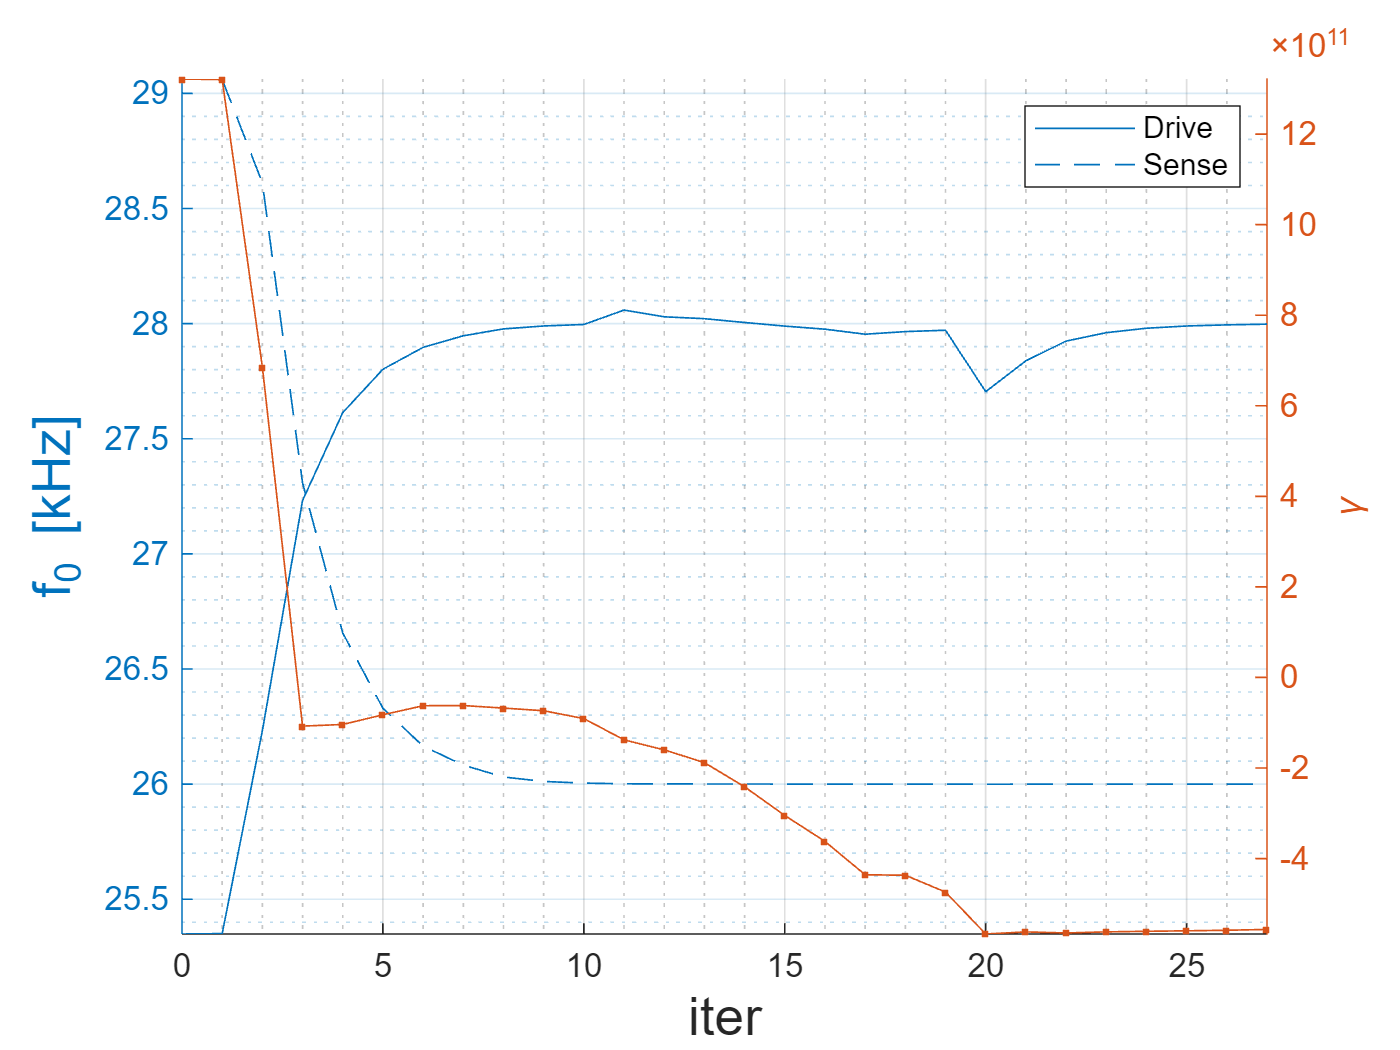

% Initial conditions x = [p]
x0 = p*0;

% Bounds
lb = -[25, 25, 1, 1, 1, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5];
ub =  [25, 25, 1, 1, 1, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5];

args.sys_fun = @(p) build_model(p); % function that evaluates the model at p

args.imod = [1 2];              % mode shape to track
args.f_target = [28 26]*1e3;    % [Hz] mode shape frequency
args.imod_gamma = 1;            % target mode for the nonlinear analysis
args.gamma_target = -1e10;

args.ConstraintTolerance = 1e-10; 

t0=tic;
[xsol,fval,history] = run_fmincon(x0, lb, ub, args);

topt = toc(t0);
fprintf(' Optimization time: %d min %.0f s\n\n', floor(topt/60), rem(topt,60))

 Optimization time: 3 min 12 s



## Optimization results

disp(xsol')

    7.1743
    0.3206
   -0.1498
   -0.2359
   -0.0627
   -1.9261
    1.6938
   -0.6548
    0.4509
   -0.8285
   -1.9720
    1.6062
   -0.6076
    0.4702
   -0.6963



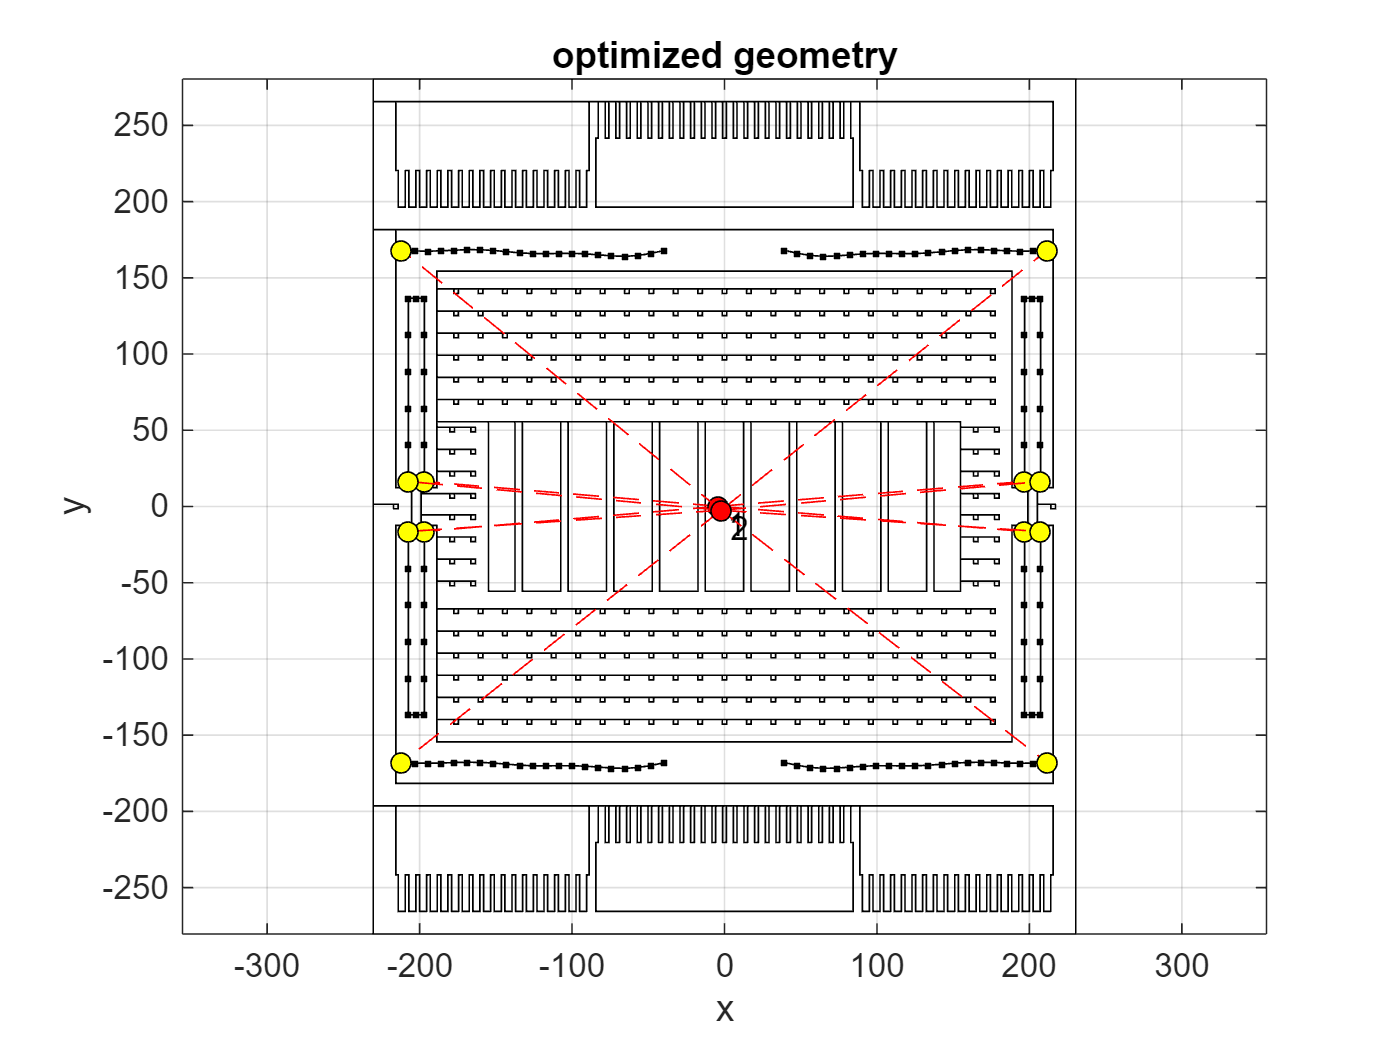

obj = build_model(xsol);
figure
obj.mpc_plot
title('optimized geometry')

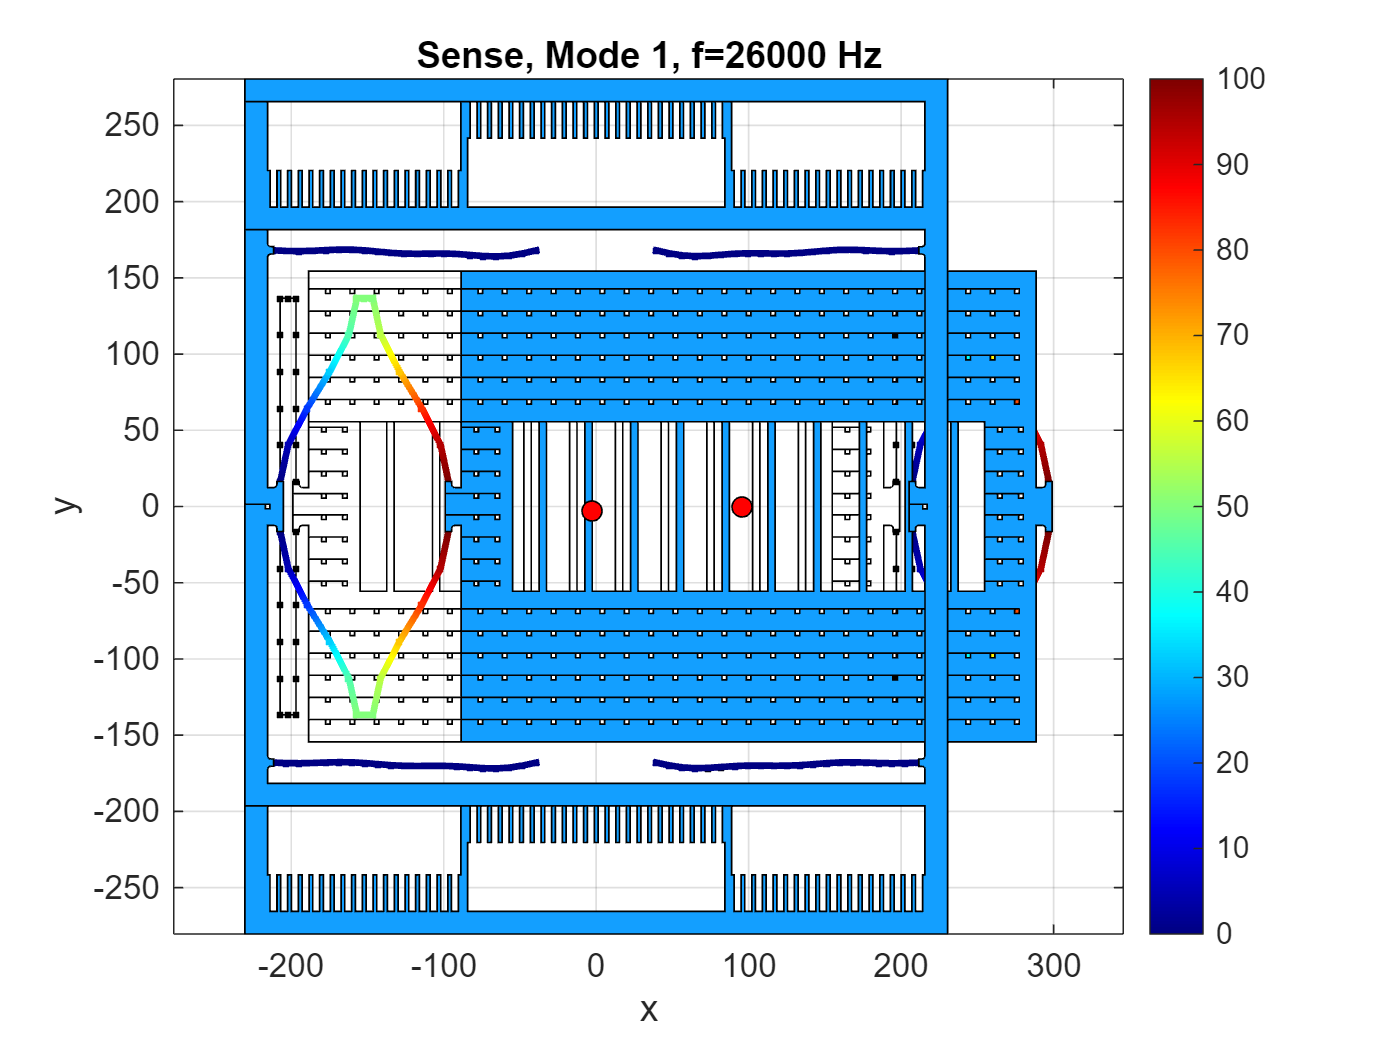

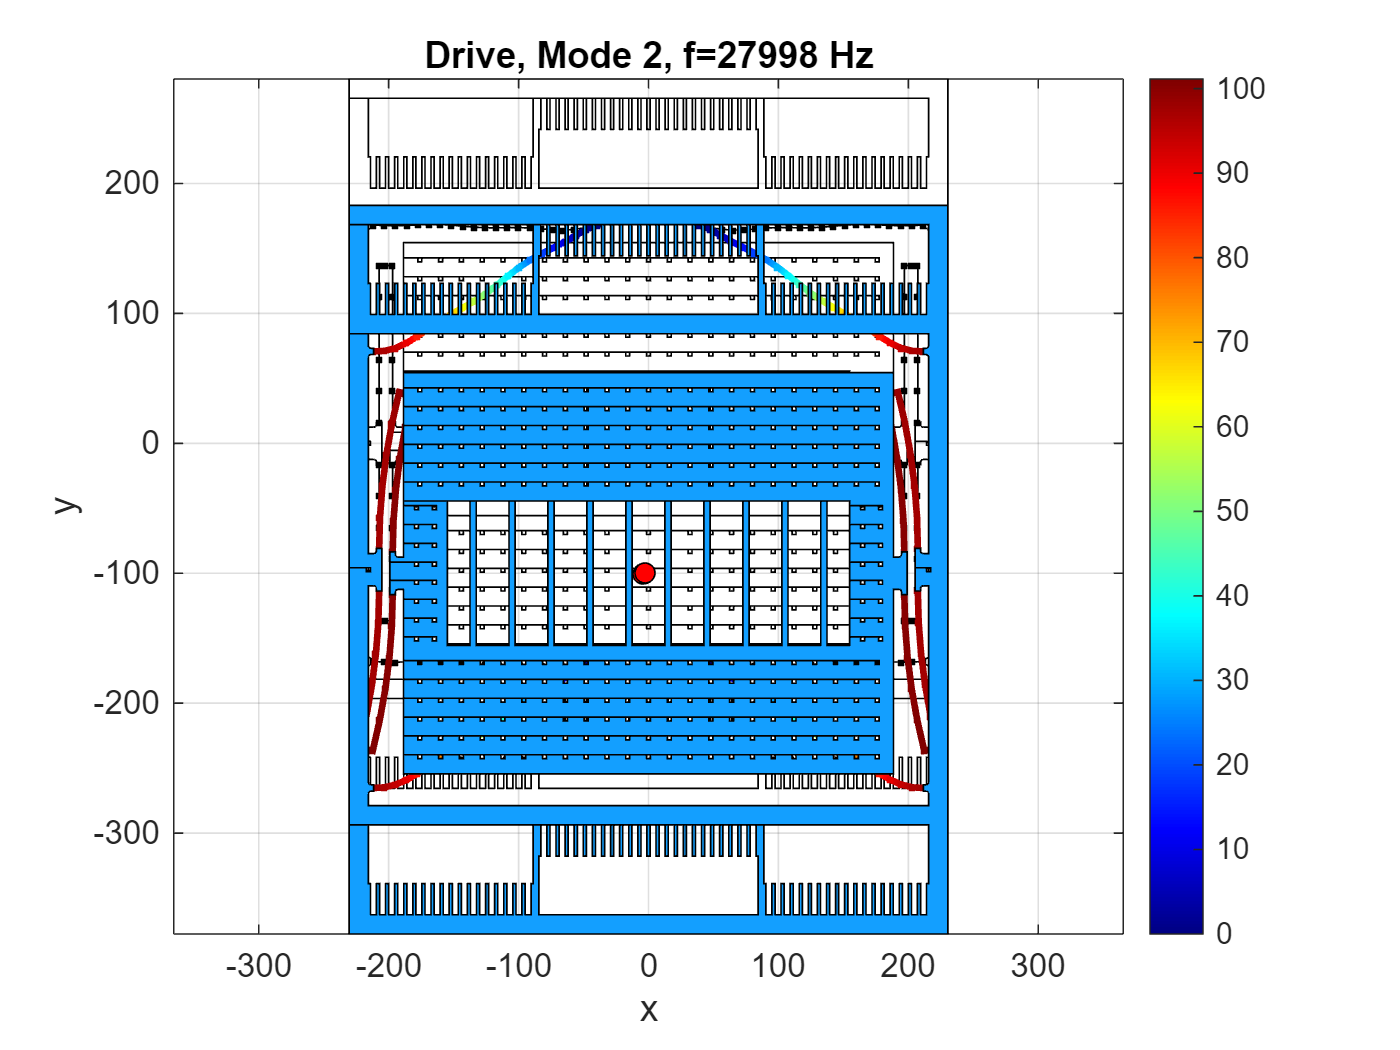

 mode: 2
 dof: 365 
 gamma = -5.56545e+11


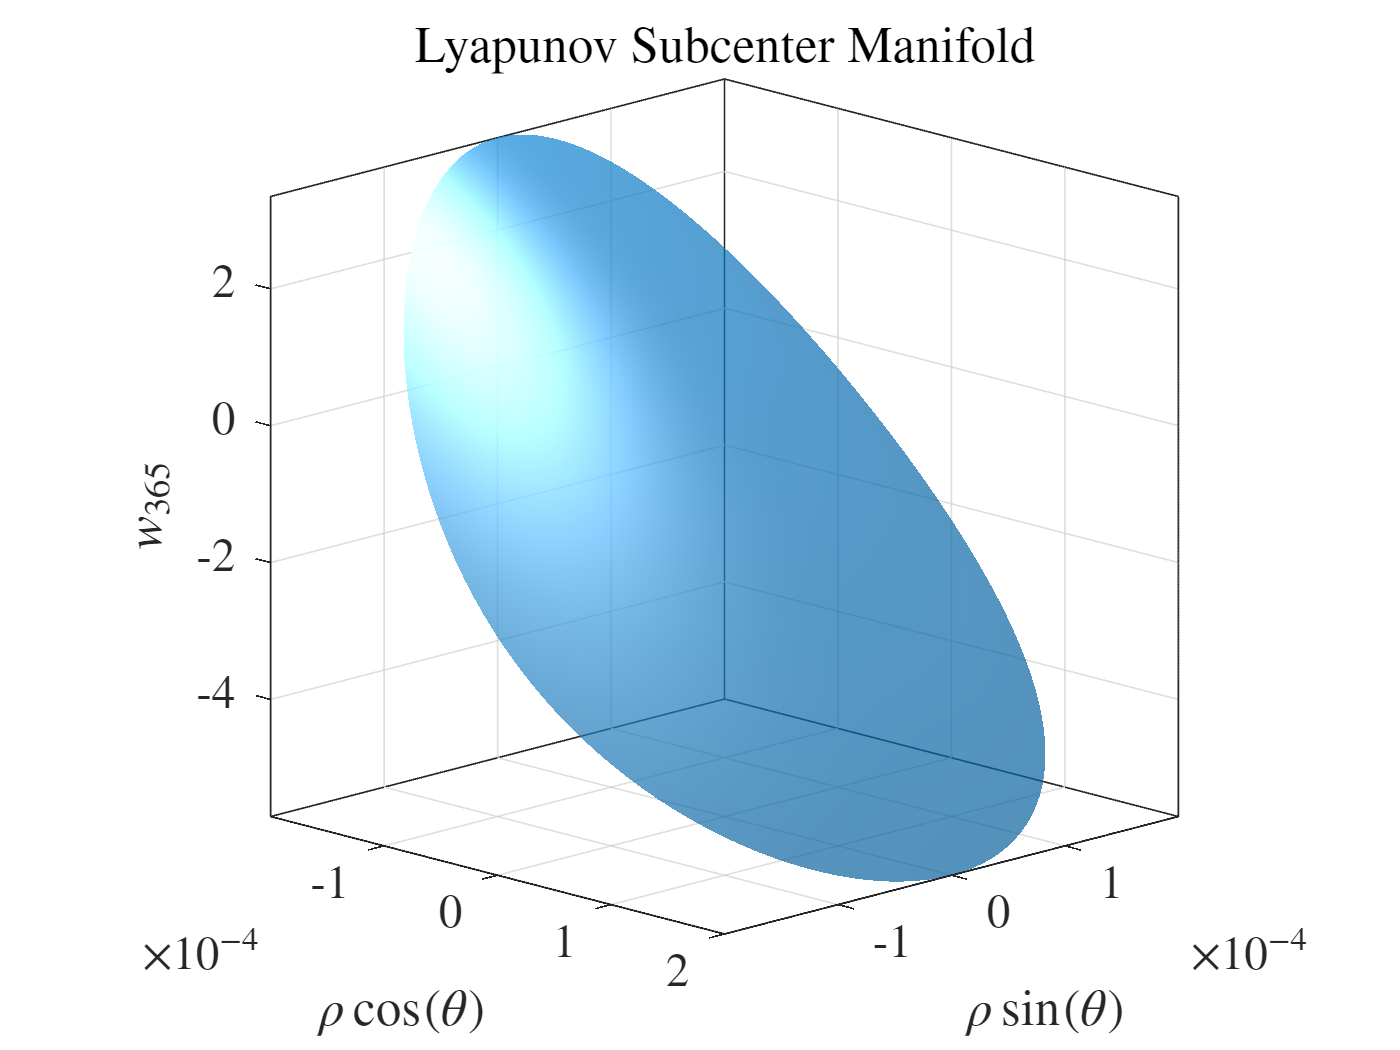

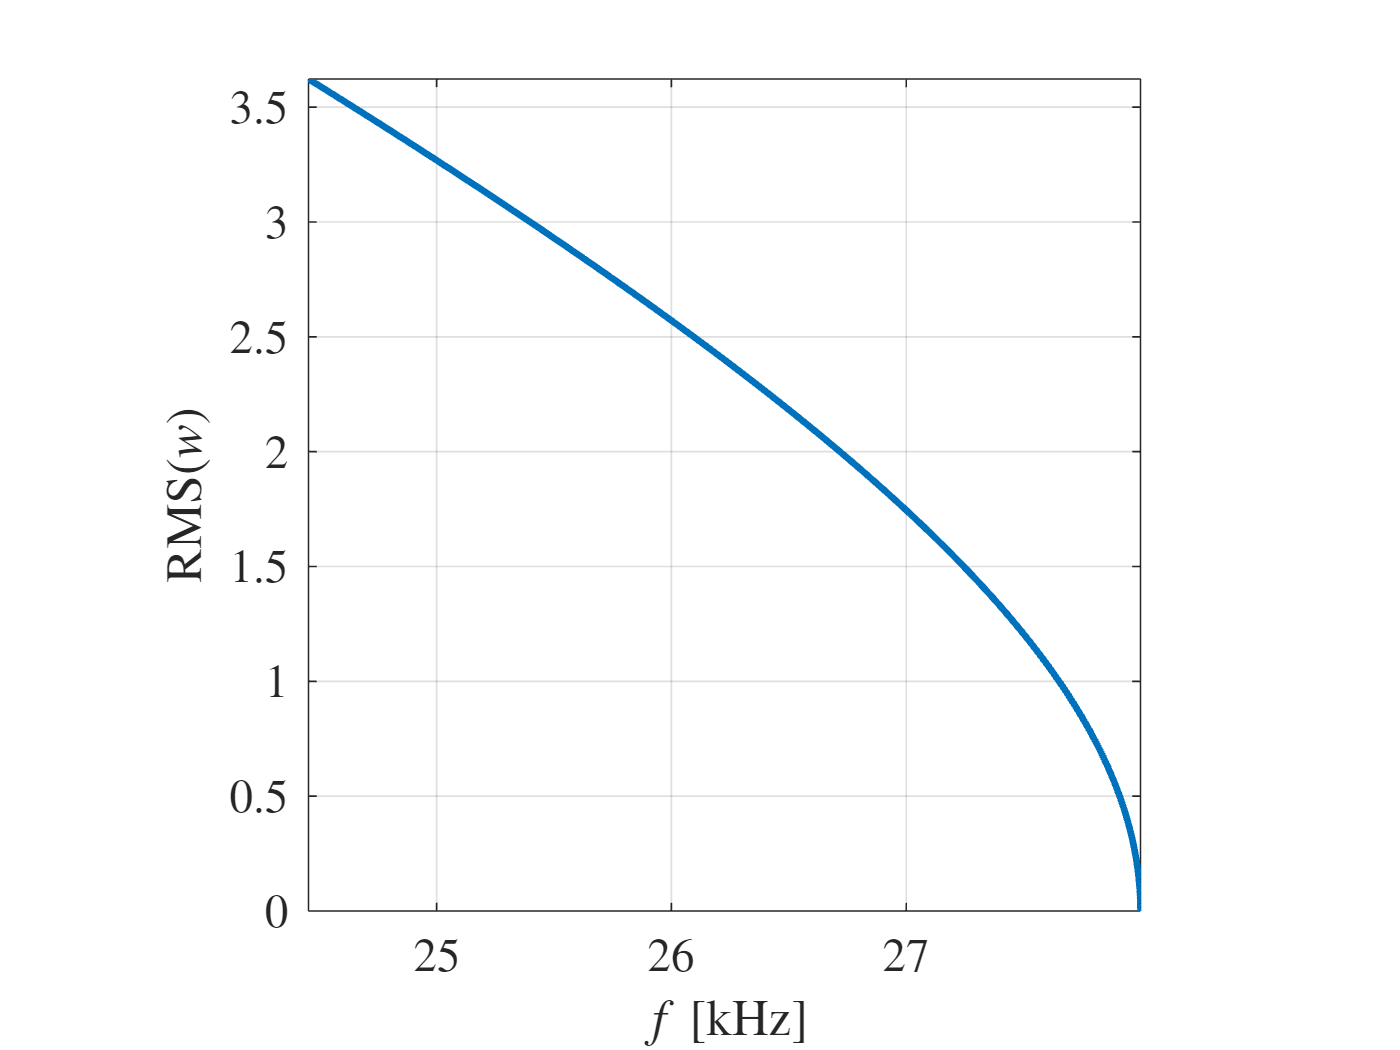

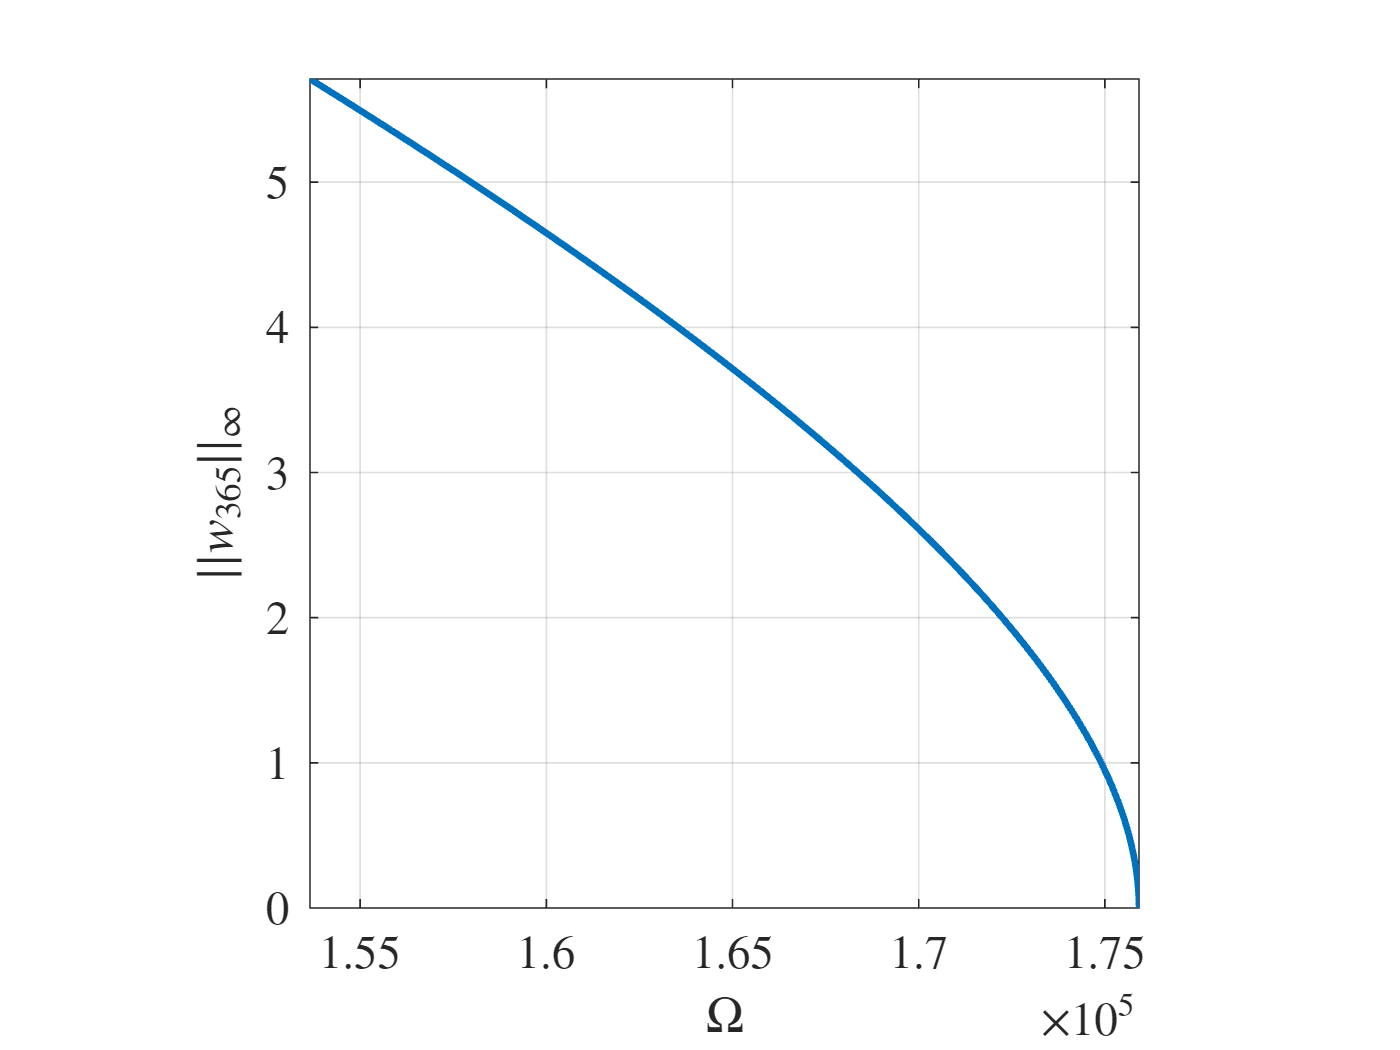

[Omega, wBB_rms, wBB_infNorm] = analyze_system(obj);

## Check accuracy using SSMtool (v2.6)

The backbone curves shown above are computed from a 3rd order LSM expansion, which is valid for low dispacements. To check the accuracy of the result for higher amplitudes, one can use the `SSMtool` expanding at higher orders.

References:

Jain, S., Li, M., Thurnher, T., & Haller, G. (2023). *SSMTool 2.6: Computation of invariant manifolds in high-dimensional mechanics problems* (v2.6). Zenodo. [https://doi.org/10.5281/zenodo.10018285](https://doi.org/10.5281/zenodo.10018285) 

 SSMTool (v2.6) added to path.

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 0
modal damping ratio for 2 mode is 0
modal damping ratio for 3 mode is 0
modal damping ratio for 4 mode is 0
modal damping ratio for 5 mode is 0
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
   1.0e+06 *

   0.0000 + 0.1634i
   0.0000 - 0.1634i
   0.0000 + 0.1759i
   0.0000 - 0.1759i
   0.0000 + 1.0345i
   0.0000 - 1.0345i
   0.0000 + 1.1006i
   0.0000 - 1.1006i
   0.0000 + 2.2161i
   0.0000 - 2.2161i

(near) outer resonance detected for the following combination of master eigenvalues
     1     1
     2     1
     2     2
     3     2
     3     3
     4     3
     4     4
     5     4
     5     5
     1     1
     1     2
   

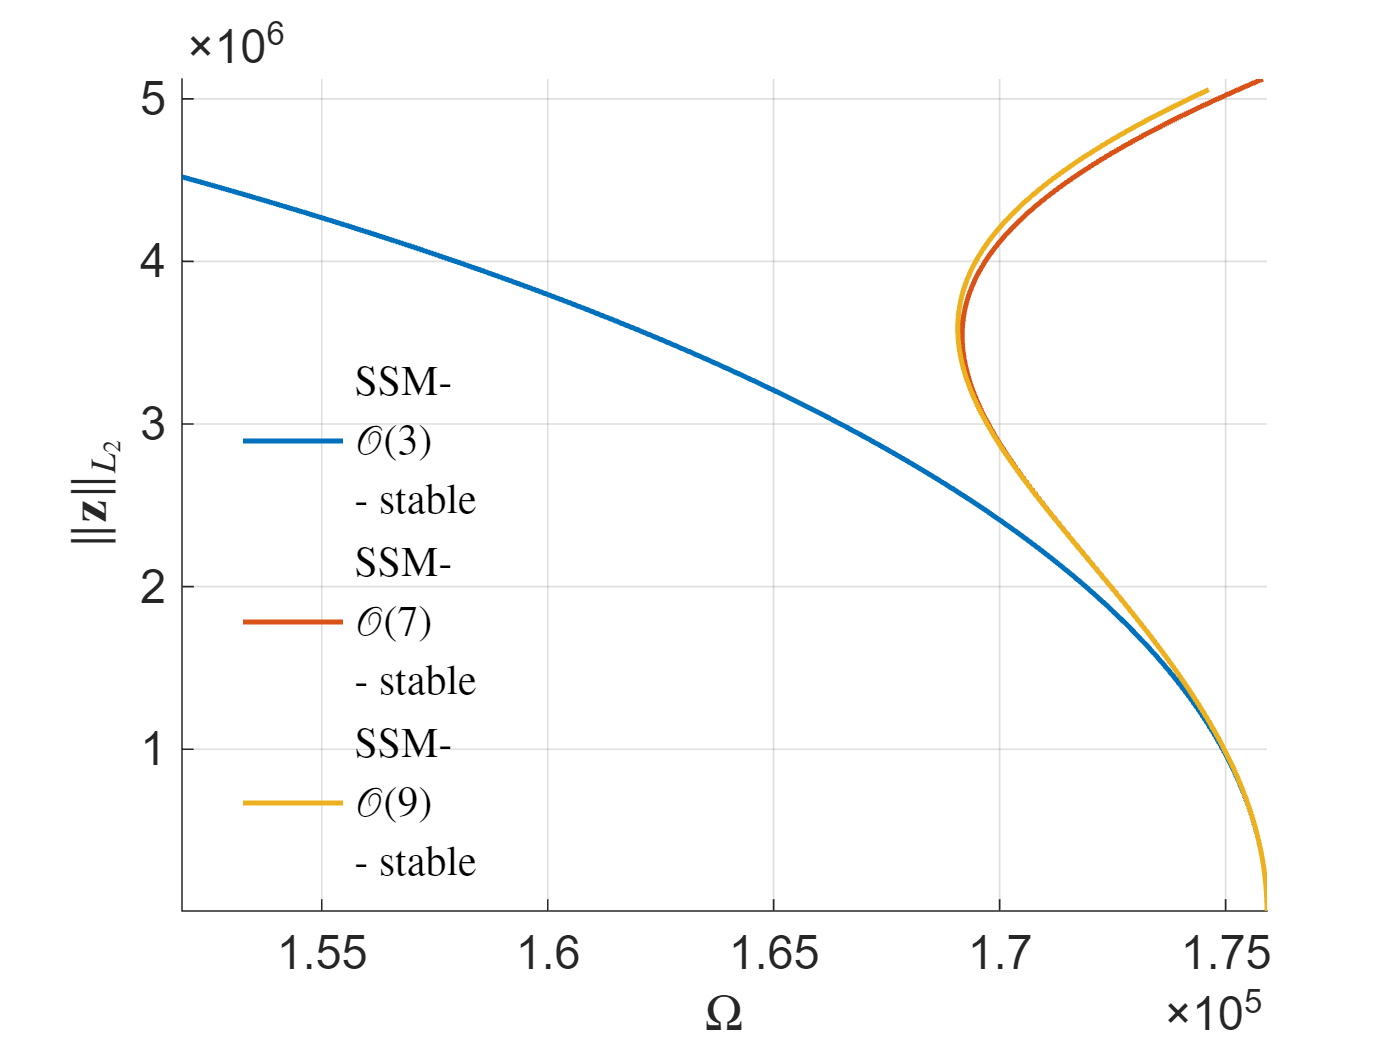

 SSMTool (v2.6) removed from path.



order = [3 7 9];
imod = 2;
bb = verify_using_SSMtool(obj, order, imod);

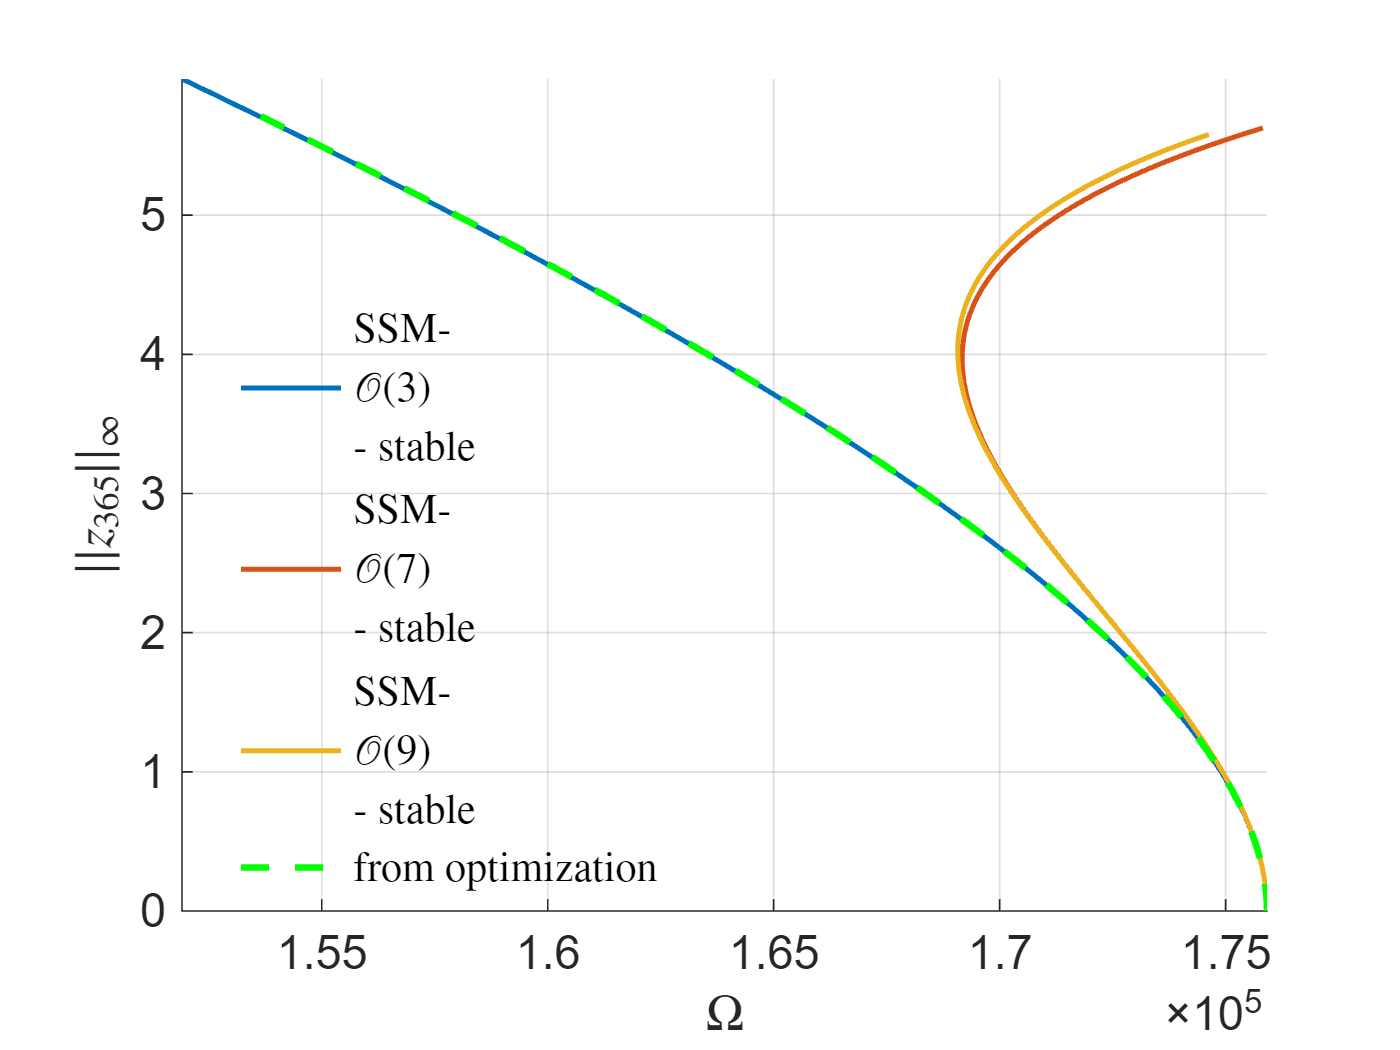

hold on;
plot(Omega, wBB_infNorm, 'g--', 'LineWidth',2,'DisplayName', 'from optimization')